clear
clc

## GRID CREATION

y1_by_x1 = 0.5;
x1 = 3;
nx = 50;
ny = round(y1_by_x1*nx)

ny = 25

y1 = (ny/nx)*x1

y1 = 1.5000


[X, Y] = MESH_GRID(0, 0, x1, y1, nx+1, ny+1);

%Time Step Calculation
dt = (X(1,2) - X(1,1))/100;
dx = (X(1,2) - X(1,1))

dx = 0.0600

dy = (Y(2,1) - Y(1,1))

dy = 0.0600

### POINT EMITTER LOCATION & POTENTIAL

xe = 0.5;
ye = y1/2;
Anode_pos = [xe,ye];
%Potential
Volt =  2;

### COLLECTOR CREATION

% Generate coordinates
NACA_digits = '0012'; % Example NACA 2412 airfoil
num_points = 200 % Number of points to generate

num_points = 200

[x, y] = CURVEGEN_Airfoil(NACA_digits, num_points,-10);
x = x+1;
y = y+y1/2;
collector = [x,y];

%Temporary CIRCLE
% [Boundary,VELOCITIES,P_NORMALS,INTERIOR] = BC_Custom_Obstacle(collector, X, Y,0);

x0 = linspace(0.8,2,200);
Ex_mean = x0*0;
Ey_mean = x0*0;

% collector = CURVEGEN_Circle(0.5+0.5,y1/2,0.15,35);


## PLOTTING ELECTRO-STATIC FIELDS (Don't Run to Save time)

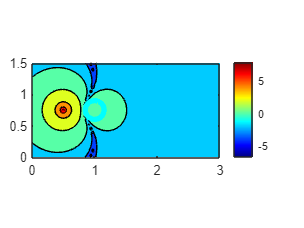

[X_plot, Y_plot] = MESH_GRID(0, 0, x1, y1, 100, 100);
[E_x,E_y,V_plot] = E_GRID(X_plot,Y_plot,collector,Anode_pos,Volt);
E_x = (E_x)/(max(max(E_x))-min(min(E_x)));
E_y = (E_y)/(max(max(E_y))-min(min(E_y)));

k = 1;
E_MAG = sqrt(E_x.*E_x + E_y.*E_y);
E_x = k*(E_x);
E_y = k*(E_y);

[~,~,~,INTERIOR1] = BC_Custom_Obstacle(collector, X_plot, Y_plot,0);

for i=1:height(INTERIOR1)
            E_x(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
            E_x(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
            E_y(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
            E_y(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
end


contourf(X_plot,Y_plot,log((abs(V_plot))),'LineStyle','-','LineWidth',0.1)
colormap("jet")
% shading interp
hold on
plot([collector(:,1);collector(1,1)],[collector(:,2);collector(1,2)],'cyan','LineWidth',4)
plot(Anode_pos(1),Anode_pos(2),'r*','MarkerSize',4,'MarkerFaceColor','r')
colorbar
cutoff = -inf;
axis equal
hold off

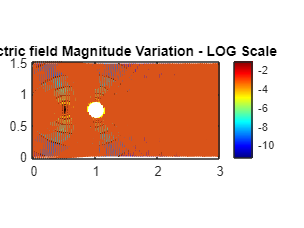


E_MAG = sqrt(E_x.*E_x + E_y.*E_y);

contourf(X_plot,Y_plot,log(E_MAG),'LineStyle','-','LineWidth',0.1)
axis equal
title("Electric field Magnitude Variation - LOG Scale")
colorbar

hold on
plot(collector(:,1), collector(:,2), 'y', 'LineWidth', 2);
quiver(X_plot(V_plot>cutoff),Y_plot(V_plot>cutoff),(E_x(V_plot>cutoff))./E_MAG(V_plot>cutoff),(E_y(V_plot>cutoff))./E_MAG(V_plot>cutoff),'LineWidth',1);
    
axis equal
hold off

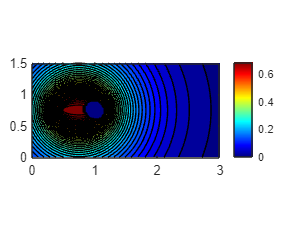

min_coll = X_plot*0;
min_emmi = X_plot*0;

for i=1:numel(X_plot)
    min_coll(i) = MIN_DISS(collector,X_plot(i),Y_plot(i));
    min_emmi(i) = MIN_DISS(Anode_pos,X_plot(i),Y_plot(i));
end

rho = exp(-min_coll).*exp(-min_emmi);
for i=1:height(INTERIOR1)
            rho(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
end

contourf(X_plot,Y_plot,(rho), 40,'LineStyle','-','LineWidth',0.1)
colorbar
axis equal

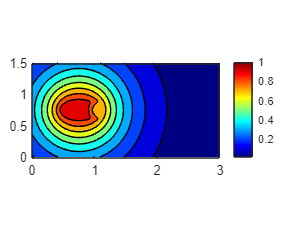

Ex1 = E_x;
Ey1 = E_y;

rho = E_x;

rho(2:end-1,2:end-1) = E_x(2:end-1,3:end)-E_x(2:end-1,1:end-2) +E_y(3:end,2:end-1)-E_y(1:end-2,2:end-1);
rho(1,:) = rho(1,:)*0;
rho(end,:) = rho(end,:)*0;
rho(:,1) = rho(:,1)*0;
rho(:,end) = rho(:,end)*0;
rho = rho/max(max(rho));
rho = calculate_charge_density(V_plot, dx, dy);
rho = exp(-min_coll).*exp(-min_emmi);
rho = rho/max(max(rho));
Ex1 = E_x.*exp(rho);
Ey1 = E_y.*exp(rho);


contourf(X_plot,Y_plot,((rho)),'LineStyle','-','LineWidth',0.1)
axis equal
colorbar

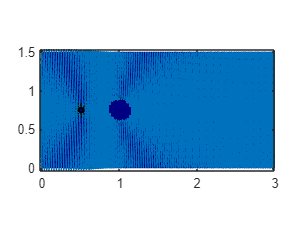

% Ex1(abs(E_MAG)<0.1*mean(mean(E_MAG))) = 0;
% Ey1(abs(E_MAG)<0.1*mean(mean(E_MAG))) = 0;
% 
Ex1(abs(E_MAG)>100*mean(mean(E_MAG))) = 0;
Ey1(abs(E_MAG)>100*mean(mean(E_MAG))) = 0;
E_MAG1 = sqrt(Ex1.*Ex1 + Ey1.*Ey1);

contourf(X_plot,Y_plot,E_MAG1,'LineStyle','-','LineWidth',0.1)

hold on
quiver(X_plot,Y_plot,Ex1./E_MAG1,Ey1./E_MAG1,'LineWidth',1);
hold off
axis equal

sum(sum(Ex1))

ans = 2.3459

mean(mean(Ex1))

ans = 2.3459e-04


rho1 = calculate_charge_density(V_plot, dx, dy);



function rho = calculate_charge_density(V, dx, dy)
    % Calculate charge density from potential field using finite difference methods
    
    % Calculate Laplacian of potential using central difference method
    dV_dx = gradient(V, dx, 2); % Compute gradient along x-axis
    dV_dy = gradient(V, dy, 1); % Compute gradient along y-axis
    d2V_dx2 = gradient(dV_dx, dx, 2); % Second derivative along x-axis
    d2V_dy2 = gradient(dV_dy, dy, 1); % Second derivative along y-axis
    
    % Calculate charge density using Poisson's equation
    rho =  (d2V_dx2 + d2V_dy2);
end

function min_distance = MIN_DISS(surface_points, x, y)
    % Calculate the least distance from a point (x, y) to a surface defined by a set of 2D points
    
    % If there is only one point in the surface_points set, return the distance to that point
    if size(surface_points, 1) == 1
        point = surface_points(1, :);
        min_distance = norm([x, y] - point);
        return;
    end
    
    % Initialize minimum distance to a large value
    min_distance = Inf;
    
    % Iterate through each line segment formed by adjacent points on the surface
    for i = 1:size(surface_points, 1) - 1
        % Extract coordinates of the current line segment
        p1 = surface_points(i, :);
        p2 = surface_points(i + 1, :);
        
        % Calculate the distance from the point to the line segment
        distance = point_to_line_distance(p1, p2, x, y);
        
        % Update the minimum distance if necessary
        min_distance = min(min_distance, distance);
    end
end

function distance = point_to_line_distance(p1, p2, x, y)
    % Calculate the distance from a point (x, y) to a line segment defined by two points p1 and p2
    
    % Compute vector components
    dx = p2(1) - p1(1);
    dy = p2(2) - p1(2);
    
    % Calculate parameters for the line equation
    a = dx^2 + dy^2;
    b = dx * (p1(1) - x) + dy * (p1(2) - y);
    c = (p1(1) - x)^2 + (p1(2) - y)^2;
    
    % Calculate the closest point on the line segment to the point (x, y)
    if a ~= 0
        t = -b / a;
        t = max(0, min(1, t)); % Ensure t is within [0, 1] to stay within the line segment
        closest_point = [p1(1) + t * dx, p1(2) + t * dy];
    else
        % Handle degenerate case where the line segment collapses to a point
        closest_point = p1;
    end
    
    % Calculate the distance between the point and the closest point on the line segment
    distance = norm([x, y] - closest_point);
end
